% P8.1
clear all
syms s
Ls_a = 1/((1 + 0.5*s)*(1 + 2*s));
Ls_b = 3*(s^2 + 1.5*s + 1)/(s - 2)^2;
Ls_c = (s - 6)/(s^2 + 5*s + 6);
Ls_d = 10*(s + 6)/(s*(s + 1)*(s + 3));

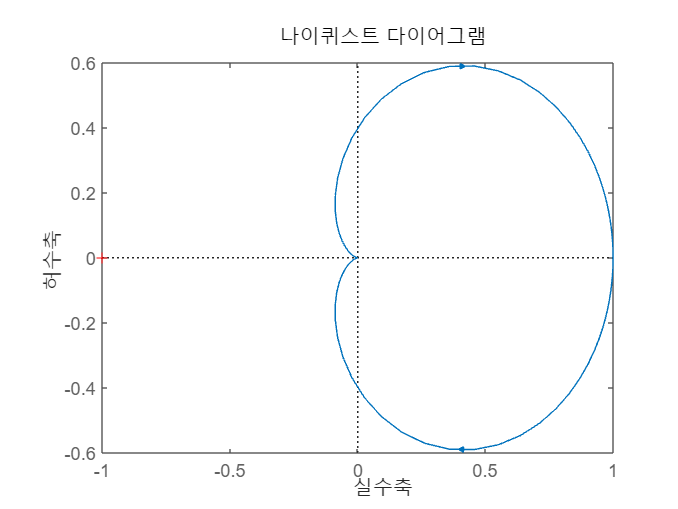

% (a)
Ls2bode(Ls_a)

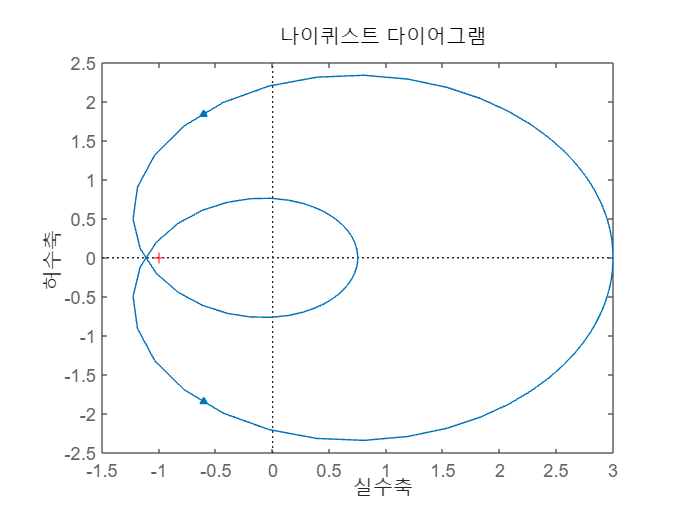

% (b)
Ls2bode(Ls_b)

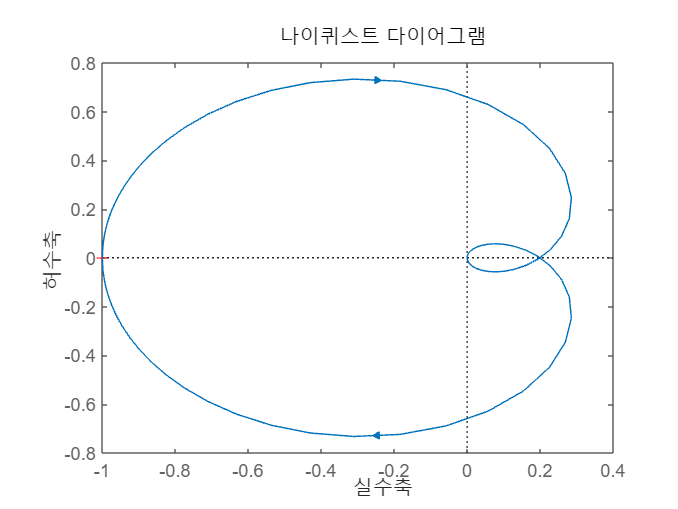

% (c)
Ls2bode(Ls_c)

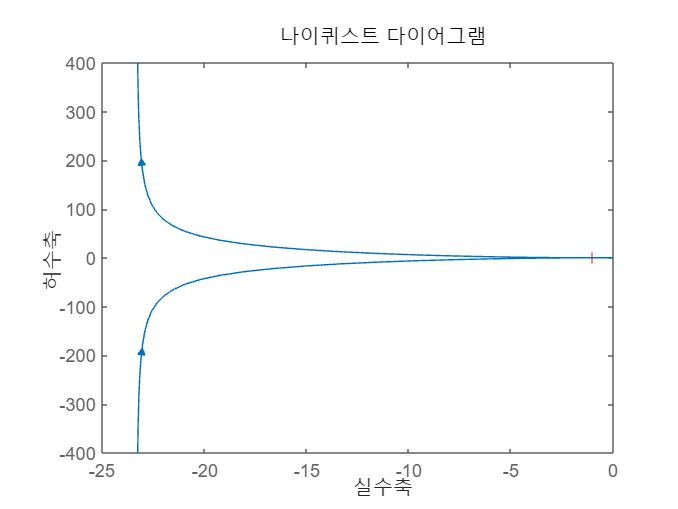

% (d)
Ls2bode(Ls_d)

function Ls2bode(inputLs) %전달함수를 넣으면 바로 극좌표선도(nyquist plot)를 그려주는 함수를 만든다.
    [n, d] = numden(inputLs);
    num = sym2poly(n);
    den = sym2poly(d);
    sys = tf(num, den);
    nyquist(sys)
end